clear; clc; close all;


## 1. Setup & System Definitions

x = casos.Indeterminates('x', 2);

% System Dynamics
f_true = [x(2); -x(1) + (1/3)*x(1)^3 - x(2)];
g_true = [0; 1];

% Initial Set X0
k_x = 0.25 - x(1)^2 - (x(2) + 3)^2;

% Unsafe Sets X_u
h1_x = x(1)^2 * (-1) - x(1)*2 - x(2)^2 - x(2)*2 - 1.84; % written out because of compilation issues with matlab
h2_x = x(1)^2 * (-1) - x(1)*2 - x(2)^2 + x(2)*2 - 1.84; % written out because of compilation issues with matlab
h_x = -h1_x * h2_x;


## 2. Data Collection (Mocking Noisy Experiment Data)

T = 80; % number of samples
w_bound = 2; % L-infinity norm bound on disturbance

% Polytopic description of disturbance W * w leq d_w, 
W = [eye(2); -eye(2)];
dw = w_bound * ones(4,1);

X_s = zeros(2, T);
U_s = zeros(1, T);
Xdot_s = zeros (2, T);
g_val = g_true;


rng(42); % for reproducability
for i = 1:T
    % Sample states and inputs randomly
    X_s(:, i) = (rand(2,1) - 0.5) * 6; % x in range [-3, 3] should give enough viable data
    U_s(i) = (rand(1,1) - 0.5) * 10; % u in range [-5, 5]
    w_noise = rand(2,1) * w_bound; % w_noise leq 2

    x_val = X_s(:, i);
    f_val = full(subs(f_true, x, x_val)); % Evaluate f with the (created) noisy data

    Xdot_s(:,i) = f_val + g_val * U_s(i) + w_noise;
end

## 3. Data-driven Consistency Set Formulation

% Prior: f is 2D cubic polynomial with f(0)=0. g is 2D constant.
phi = [x(1); x(2); x(1)^2; x(1)*x(2); x(2)^2;...
         x(1)^3; x(1)^2*x(2); x(1)*x(2)^2; x(2)^3];
num_phi = length(phi);

gamma_basis = 1; % Constant
num_gamma = 1;

gamma_eval = gamma_basis;
% Construct Matrices A, B, xi from Paper
A = []; B = []; xi = [];
for i = 1:T
    phi_eval = full(subs(phi, x, X_s(:,i)));

    % Kronecker products (See (13) from Paper)
    A = [A; kron(W, phi_eval')];
    B = [B; kron(W, U_s(i) * gamma_eval')];
    xi = [xi; W * Xdot_s(:,i)];
end

% Create Matrix N and e
% Dimensions: N = [324 x 22], e = [324 x 1]
N = [A, B, zeros(4*T, 2); zeros(4, 2*num_phi), zeros(4, 2*num_gamma), W];
e = [xi - kron(ones(T,1), dw); dw];
num_faces = size(N,1); % number of rows


## 4. SOS Program Setup

% Implementing Density Function
% nabla * [rho(x)*f(x) + psi(x)g(x) + rho(x)w] - rho(x) h(x) > 0

rho = casos.PS.sym('rho', monomials(x, 0:4));
psi = casos.PS.sym('psi', monomials(x, 0:4));

% creating vector y for Equation (17)
% y^T(x)*N = r(x) and y^T(x)*e < - rho(x)*h(X)
% Dimension: y_vec = [324 x 1]
y_cell = cell(num_faces, 1);
for i = 1:num_faces
    y_cell{i} = casos.PS.sym(sprintf('y%d', i), monomials(x, 0:1), 'gram');
end
y_vec = vertcat(y_cell{:});

% Creating r(x)
% r(x) = -[nabla * [rho(I_n kronProd phi^T)] nabla * [psi(I_n kronProd gamma^T)] nabla rho]
r1_1 = casos.PS(zeros(1, num_phi));
r1_2 = casos.PS(zeros(1, num_phi));
for i = 1:num_phi
    r1_1(i) = nabla(rho * phi(i), x(1));
    r1_2(i) = nabla(rho * phi(i), x(2));
end
r1 = [r1_1, r1_2]; % Dimension: [1 x 18]

r2 = [nabla(psi * 1, x(1)), nabla(psi * 1, x(2))];

r3 = [nabla( rho, x(1)), nabla(rho, x(2))];

r_x = [r1, r2, r3]; % Dimension [1 x 22]


## 5. Setting up SOS Constraints

% slack constants for strict inequalities
c1 = 1e-4;
c2 = 1e-4;

% Contraint (A.1)
eq_constr = (y_vec.' * N) - r_x;
size(eq_constr);

% Constraint (A.2)
ineq1 = -rho * h_x - (y_vec.' * e) - c1;
size(ineq1);

% Constraint (A.3)
ineq2 = -rho * h_x - psi;
ineq3 = -rho * h_x + psi;
size(ineq2);
size(ineq3);
% Constraint (A.5)
% S-procedure multipliersv
s1 = casos.PS.sym('s1', monomials(x, 0:2), 'gram');
s2 = casos.PS.sym('s2', monomials(x, 0:2), 'gram');


% Constraint (A.4)
ineq5 = -rho - k_x * s2 - c2;
ineq4 = rho - k_x * s1;


## 6. Solve via CASOS

vars = [rho; psi; y_vec; s1; s2];

% Build CASOS structure
sos = struct('x', vars,...
 'g', [eq_constr.'; -eq_constr.'; ineq1; ineq2; ineq3; ineq4; ineq5], ...
 'f', 0);
opts.Kc = struct('lin', 44, 'sos', 5);
opts.error_on_fail = false;

% Execute solver
S = casos.sossol('S', 'mosek', sos, opts);

sol = S('p', []);

rho_sol = sol.x(1);
psi_sol = sol.x(2);


## 7. Plot 

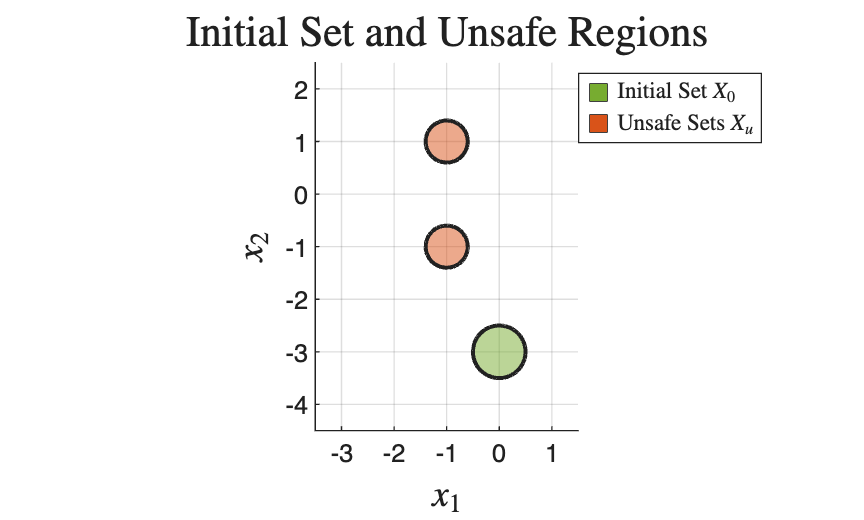

%% 8. Visualization of Sets
% Define the grid for plotting
x1_range = linspace(-4, 3, 400); % Adjust bounds based on your system
x2_range = linspace(-4, 3, 400);
[X1, X2] = meshgrid(x1_range, x2_range);

% Evaluate the polynomials manually using element-wise operations
% Initial Set X0: k_x >= 0
K_val = 0.25 - X1.^2 - (X2 + 3).^2;

% Unsafe Sets Xu: h1_x >= 0 and h2_x >= 0
H1_val = -(X1.^2) - 2.*X1 - (X2.^2) - 2.*X2 - 1.84;
H2_val = -(X1.^2) - 2.*X1 - (X2.^2) + 2.*X2 - 1.84;

% Initialize Figure
figure('Name', 'System Sets', 'Color', 'w');
hold on; grid on; axis equal;
xlabel('$x_1$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$x_2$', 'Interpreter', 'latex', 'FontSize', 14);
title('Initial Set and Unsafe Regions', 'Interpreter', 'latex', 'FontSize', 16);

% Plot Initial Set (X0) in Green
% contourf with [0 0] plots exactly the boundary where K_val == 0 and fills the >= 0 region
[~, hK] = contourf(X1, X2, K_val, [0 0], 'FaceColor', '#77AC30', 'FaceAlpha', 0.5, 'LineWidth', 1.5);

% Plot Unsafe Sets (Xu) in Red
[~, hU1] = contourf(X1, X2, H1_val, [0 0], 'FaceColor', '#D95319', 'FaceAlpha', 0.5, 'LineWidth', 1.5);
[~, hU2] = contourf(X1, X2, H2_val, [0 0], 'FaceColor', '#D95319', 'FaceAlpha', 0.5, 'LineWidth', 1.5);

% Add a dummy plot for the legend (contourf handles don't always behave well in legends)
p_safe = plot(NaN, NaN, 's', 'MarkerSize', 10, 'MarkerFaceColor', '#77AC30', 'MarkerEdgeColor', 'k');
p_unsafe = plot(NaN, NaN, 's', 'MarkerSize', 10, 'MarkerFaceColor', '#D95319', 'MarkerEdgeColor', 'k');
legend([p_safe, p_unsafe], {'Initial Set $X_0$', 'Unsafe Sets $X_u$'}, 'Interpreter', 'latex', 'Location', 'best');

% Adjust limits for better viewing
xlim([-3.5, 1.5]);
ylim([-4.5, 2.5]);
hold off;

## 8. Plotting Learned Density Funcion

%% 9. Plotting the Learned Density Function (rho)
% Define a slightly smaller grid for the loop to keep computation time reasonable
x1_rho = linspace(-4, 3, 100); 
x2_rho = linspace(-4, 3, 100);
[X1_rho, X2_rho] = meshgrid(x1_rho, x2_rho);

% Preallocate the result matrix
Rho_val = zeros(size(X1_rho));

disp('Evaluating rho(x) over the grid. This might take a moment...');

Evaluating rho(x) over the grid. This might take a moment...



% Loop through each point because CASOS subs is not vectorized
for i = 1:size(X1_rho, 1)
    for j = 1:size(X1_rho, 2)
        % Extract the 2x1 state vector for this specific grid point
        current_x = [X1_rho(i,j); X2_rho(i,j)];
        
        % Substitute and store the evaluated scalar
        Rho_val(i,j) = full(subs(rho_sol, x, current_x));
    end
end
disp('Evaluation complete!');

Evaluation complete!


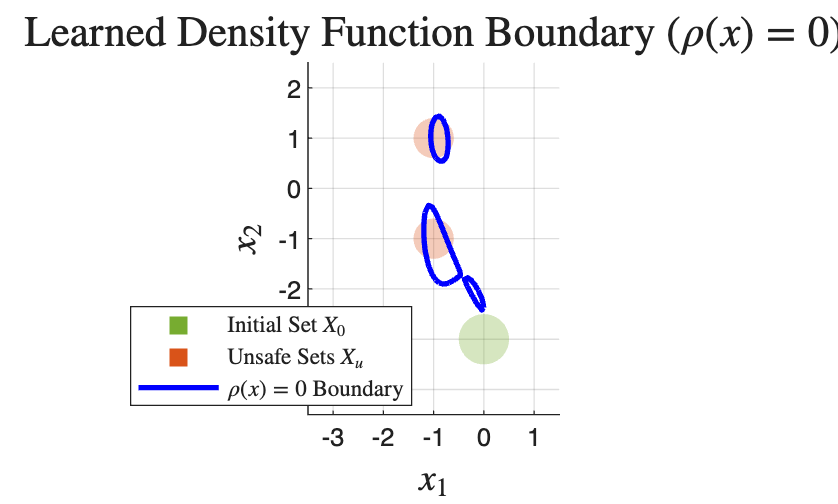


% Initialize Figure and plot the previous sets for context
figure('Name', 'Density Function Level Set', 'Color', 'w');
hold on; grid on; axis equal;
xlabel('$x_1$', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$x_2$', 'Interpreter', 'latex', 'FontSize', 14);

% Re-plot the Initial and Unsafe sets using the previous high-res grid (X1, X2)
contourf(X1, X2, K_val, [0 0], 'FaceColor', '#77AC30', 'FaceAlpha', 0.3, 'LineStyle', 'none');
contourf(X1, X2, H1_val, [0 0], 'FaceColor', '#D95319', 'FaceAlpha', 0.3, 'LineStyle', 'none');
contourf(X1, X2, H2_val, [0 0], 'FaceColor', '#D95319', 'FaceAlpha', 0.3, 'LineStyle', 'none');

% Plot the zero-level set of the density function using the evaluated Rho_val
[~, hRho] = contour(X1_rho, X2_rho, Rho_val, [0 0], 'LineColor', 'b', 'LineWidth', 2);

title('Learned Density Function Boundary ($\rho(x) = 0$)', 'Interpreter', 'latex', 'FontSize', 16);
xlim([-3.5, 1.5]);
ylim([-4.5, 2.5]);

% Legend
p_safe = plot(NaN, NaN, 's', 'MarkerSize', 10, 'MarkerFaceColor', '#77AC30', 'MarkerEdgeColor', 'none');
p_unsafe = plot(NaN, NaN, 's', 'MarkerSize', 10, 'MarkerFaceColor', '#D95319', 'MarkerEdgeColor', 'none');
p_rho = plot(NaN, NaN, '-b', 'LineWidth', 2);
legend([p_safe, p_unsafe, p_rho], {'Initial Set $X_0$', 'Unsafe Sets $X_u$', '$\rho(x) = 0$ Boundary'}, 'Interpreter', 'latex', 'Location', 'best');

hold off;

## 9. Simulating Closed Loop System

%% 10. Closed-Loop Simulation
% Define simulation time and initial state
t_span = [0, 10]; % Simulate for 10 seconds
x0_sim = [0; -3]; % Center of the initial set X0

% Define the closed-loop dynamics as an anonymous function pointing to our helper
% We pass the CASOS indeterminates (x) and the solved polynomials
closed_loop_dyn = @(t, x_curr) eval_dynamics(t, x_curr, x, rho_sol, psi_sol);

disp('Simulating closed-loop system... (This may take a few minutes due to symbolic evaluation)');

Simulating closed-loop system... (This may take a few minutes due to symbolic evaluation)


[t_sim, x_sim] = ode45(closed_loop_dyn, t_span, x0_sim);

disp('Simulation complete!');

Simulation complete!


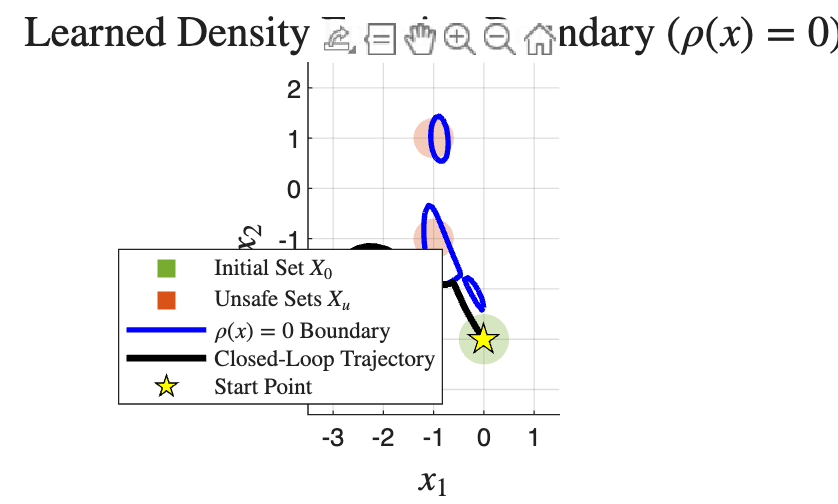


% Plot the resulting trajectory on the existing figure
figure(gcf); % Bring up the most recently active figure
hold on;

% Plot trajectory and start point
p_traj = plot(x_sim(:,1), x_sim(:,2), '-k', 'LineWidth', 2.5);
p_start = plot(x0_sim(1), x0_sim(2), 'pk', 'MarkerSize', 12, 'MarkerFaceColor', 'y', 'MarkerEdgeColor', 'k');

% Update the legend to include the new simulation elements
legend([p_safe, p_unsafe, p_rho, p_traj, p_start], ...
    {'Initial Set $X_0$', 'Unsafe Sets $X_u$', '$\rho(x) = 0$ Boundary', 'Closed-Loop Trajectory', 'Start Point'}, ...
    'Interpreter', 'latex', 'Location', 'best');
hold off;



%% Helper Function for ODE Dynamics
% Note: In modern MATLAB (R2016b+), helper functions can be placed at the very bottom of a script.
function dxdt = eval_dynamics(t, x_curr, x_sym, rho_sol, psi_sol)
    % 1. Evaluate Controller u(x) = psi(x) / rho(x)
    % We use full(subs(...)) to get numeric scalars from the CASOS objects
    rho_val = full(subs(rho_sol, x_sym, x_curr));
    psi_val = full(subs(psi_sol, x_sym, x_curr));
    
    % Prevent division by zero if trajectory touches the exact boundary of rho
    if abs(rho_val) < 1e-6
        rho_val = sign(rho_val) * 1e-6; 
    end
    u_val = psi_val / rho_val;

    % 2. Evaluate System Dynamics f(x) and g(x) natively for speed
    f_val = [x_curr(2); -x_curr(1) + (1/3)*x_curr(1)^3 - x_curr(2)];
    g_val = [0; 1];
    
    % 3. Apply a time-varying disturbance w(t) 
    % Bounded by the L-infinity norm w_bound = 2 from your setup
    w_val = [2 * sin(t); 2 * cos(sqrt(2)*t)]; 
    
    % 4. Compute state derivative: x_dot = f(x) + g(x)u + w
    dxdt = f_val + g_val * u_val + w_val;
end